
Root = "HardwareMeasurements";
Setup = "ProtoLab_setup_45_2110";
SampleFreq = "fs_" + 4000 + "_Hz";
SignalType = "manual_processed_signals";
Type = "Open_loop"

Type = "Open_loop"

ChildFolder = "MeasurementOrder";


Path = Root + "/" + Setup + "/" +  SampleFreq + "/" +  SignalType + "/" + Type + "/" +  ChildFolder 

Path = "HardwareMeasurements/ProtoLab_setup_45_2110/fs_4000_Hz/manual_processed_signals/Open_loop/MeasurementOrder"

Data = GetData(1,Path);
Data = Data.Data;

L = Data.calculatedData.L;
H = Data.calculatedData.H;
f = Data.calculatedData.f;
Coh = Data.calculatedData.Coh;  

ControllerData = load("Controllers/Load_Controller_V2_lowpass_13_5Hz")

ControllerData = struct with fields:
    shapeit_data: [1×1 struct]


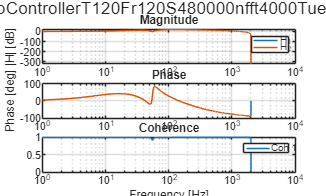

ans =   Figure (16) with properties:

      Number: 16
        Name: ''
       Color: [1 1 1]
    Position: [583 398 560 337.4462]
       Units: 'pixels'

  Show all properties


ControllerData = ControllerData.shapeit_data;
H_model = squeeze(freqresp(ControllerData.C_tf_z,2*pi.*f));
mybode(f,[H,H_model],Coh,replace(Data.FileName,'_',''))

%Measurment Name
Root = "HardwareMeasurements";
Setup = "ProtoLab_setup_45_2110";
SampleFreq = "fs_" + 4000 + "_Hz";
SignalType = "measured_signals";
ChildFolder = "MeasurementOrder";
MeasurementName = "OpenLoopController";

Number = 3

Number = 3


Path = Root + "/" + Setup + "/" +  SampleFreq + "/" +  SignalType + "/" +  ChildFolder 

Path = "HardwareMeasurements/ProtoLab_setup_45_2110/fs_4000_Hz/measured_signals/MeasurementOrder"

%Measurement Type (1: Closed_loop, 0: Open_loop)
measurementType = 0;

model ='Hardware_Openloop_FRF_setup' %'Hardware_FRF_setup'

model = 'Hardware_Openloop_FRF_setup'

%Open loop settings
signalNames = ["d","y","u","e","r"];
inName = "d";
outName = "u";


% ------------------ FRF setttings --------------------------%
frames = 120 %amount of frames

frames = 120

RawData = GetData(Number,Path);
RawData = RawData.Data;
Trun = RawData.settings.runtime;
Fs = RawData.settings.fs;

vars = struct();
for X = signalNames
    if(isfield(RawData.signals,X))
        vars.(X) = RawData.signals.(X);
        if(inName == X) 
            in = vars.(X);
        end
        if(outName == X)
            out = vars.(X);
        end
    end
end


vars = struct with fields:
    d: [480000×1 double]
    y: [480000×1 double]
    u: [480000×1 double]
    e: [480000×1 double]
    r: [480000×1 double]


% ------------------ Calculated by program --------------------------%
Path = Root + "/" + Setup + "/" +  SampleFreq

Path = "HardwareMeasurements/ProtoLab_setup_45_2110/fs_4000_Hz"

if(measurementType == 1 && isempty(C_total))
    error("Controller not defined");
end

samples = Trun*Fs; %measurement size per duration(samples)
nfft = Trun/frames*Fs;
Fres = Fs/nfft

Fres = 1


%processing
noverlap = floor(nfft/2);
window = hann(nfft);

switch (measurementType)
    case 1 % Closed_loop
        % 2-point method
        [f, H, S, L, Coh, C_resp] = twoPoint(vars.d, vars.u, vars.r, C_total, window, noverlap, nfft, Fs);
        
        %store 2-point data
        measurementName = Measurement + "_T" + Trun + "_Fr" + frames + "_S" + samples + "_nfft" + nfft;
        saveMeasurement(...
        struct("runtime", Trun, "fs", Fs, "samples", samples,"nfft", nfft,"noverlap", noverlap,"window", window, "fres", Fres, "C_res", C_resp), ...%settings    
        struct("r", vars.r, "d",vars.d,"u",vars.u,"e",vars.e,"y",vars.y), ... %signals
        struct("f",f,"H",H,"S",S, "L", L,"Coh",Coh, "C",C_resp), ...%calculatedData
        Path + '/manual_processed_signals/2_point/'+ measurementName);

        % 3-point method
        [f, H, S, Coh, C_est, L_est] = threePoint(vars.d,vars.e,vars.u,window,noverlap,nfft,Fs);

        %store 3-point data
        measurementName = Measurement + "_T" + Trun + "_Fr" + frames + "_S" + samples + "_nfft" + nfft;
        saveMeasurement(...
        struct("runtime", Trun, "fs", Fs, "samples", samples,"nfft", nfft,"noverlap", noverlap,"window", window, "fres", Fres,"C_res", C_est), ...%settings    
        struct("r", vars.r, "d",vars.d,"u",vars.u,"e",vars.e,"y",vars.y), ... %signals
        struct("f",f,"H",H,"S",S,"L",L_est, "Coh",Coh, "C",C_est), ...%calculatedData
        Path + '/manual_processed_signals/3_point/'+ measurementName);
    otherwise % Open_loop
        %H = out/in
        [H_est,f_est] = tfestimate(in,out,window,noverlap,nfft,Fs);
        [Ch, ~] = mscohere(in,out,window,noverlap,nfft,Fs);

        %store open loop frf data
        measurementName = Measurement + "_T" + Trun + "_Fr" + frames + "_S" + samples + "_nfft" + nfft;
        saveMeasurement(...
        struct("runtime", Trun, "fs", Fs, "samples", samples,"nfft", nfft,"noverlap", noverlap,"window", window, "fres", Fres), ...%settings    
        struct("r", vars.r, "d",vars.d,"u",vars.u,"e",vars.e,"y",vars.y), ... %signals
        struct("f",f_est,"H",H_est,"S",[],"L",[], "Coh",Ch, "C",[]), ...%calculatedData
        Path + '/manual_processed_signals/Open_loop/'+ measurementName);
end